# Problem 1

interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);  
set(groot, 'defaultAxesTickLabelInterpreter',interr);  
set(groot, 'defaultLegendInterpreter',interr);

## Preliminary Calculations

Re = 6378.1; % Earth radius, km
mu = 398600.4415; % Earth mu, km^3/s^2

a0 = 4.5 * Re;
th0_deg = 125; th0 = deg2rad(th0_deg);
if th0 > pi
    th0 = th0 - 2*pi
    th0_deg = rad2deg(th0)
end

dw_deg = +30; dw = deg2rad(dw_deg)

dw = 0.5236

e0 = 0.75;

## Part a)

p0 = a0*(1-e0^2)

p0 = 1.2557e+04

rmag = p0/(1+e0*cos(th0))

rmag = 2.2037e+04

r = [1 0]' * rmag

r = 	1.0e+04 *

    2.2037
         0


v0mag = sqrt(mu*(2/rmag - 1/a0))

v0mag = 4.7210

h0 = sqrt(mu*p0)

h0 = 7.0747e+04

th0dot = h0/rmag^2

th0dot = 1.4569e-04

gamma = acos(rmag*th0dot/v0mag); gamma = gamma * bpsk((sign(gamma) == sign(th0))), gamma_deg = rad2deg(gamma)

gamma = 0.8230

gamma_deg = 47.1543

v0 = v0mag * [sin(gamma), cos(gamma)]'

v0 =     3.4614
    3.2104


## Part b)

rp0 = a0*(1-e0)

rp0 = 7.1754e+03

rpN = 2*Re

rpN = 1.2756e+04

thN = th0 - dw, thN_deg = rad2deg(thN)

thN = 1.6581

thN_deg = 95.0000

eN = (rmag/rpN - 1)/(1-rmag/rpN*cos(thN))

eN = 0.6323

pN = rmag*(1+eN*cos(thN))

pN = 2.0822e+04

aN = pN / (1-eN^2)

aN = 3.4694e+04

vNmag = sqrt(mu*(2/rmag - 1/aN)), min_dv = vNmag - v0mag

vNmag = 4.9686

min_dv = 0.2476

[gammaN,hN] = getfpa(mu,pN,rmag,vNmag,thN), gammaN_deg = rad2deg(gammaN)

gammaN = 0.5880

hN = 9.1103e+04

gammaN_deg = 33.6896

vN = vNmag*[sin(gammaN), cos(gammaN)]'

vN =     2.7561
    4.1342


dv = vN - v0

dv =    -0.7054
    0.9237


dgamma = gammaN - gamma, dgamma_deg = rad2deg(dgamma)

dgamma = -0.2350

dgamma_deg = -13.4647

dvmag = norm(dv) % dvmag = sqrt(vNmag^2 + v0mag^2 - 2*vNmag*v0mag*cos(dgamma))

dvmag = 1.1622

beta = asin(sin(dgamma)/dvmag*vNmag), beta = [beta pi-beta]

beta = -1.4752

beta =    -1.4752    4.6167


beta_deg = rad2deg(beta(2))

beta_deg = 264.5202

alpha = -acos(dot(dv,v0)/(dvmag*v0mag))

alpha = -1.4752

alpha_deg = rad2deg(alpha)

alpha_deg = -84.5202

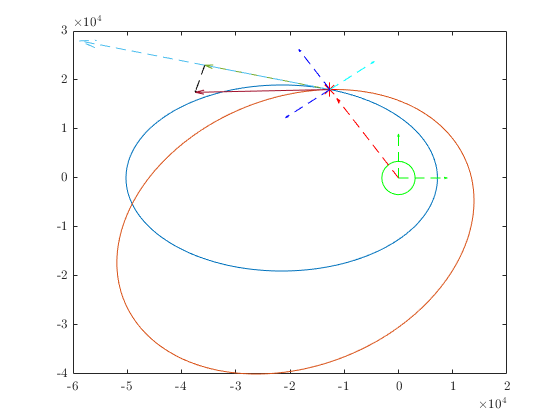

% Plotting
thplot = linspace(0,2*pi,2^10);
rplot = p0./(1+e0*cos(thplot));
rx = rplot.*cos(thplot); ry = rplot.*sin(thplot);
ogorbit = plot(rx,ry);
iCr = [cos(th0) -sin(th0); sin(th0) cos(th0)];
vNplot = iCr * vN;
v0plot = iCr * v0;
dvplot = iCr * dv;
hold on
rNplot = pN./(1+eN*cos(thplot));
rNx = rNplot.*cos(thplot+dw); rNy = rNplot.*sin(thplot+dw);
neworbit = plot(rNx,rNy);
plot(0,0,'go','markersize',25)
plot(rmag*cos(th0),rmag*sin(th0),'r*','markersize',10)
quiver(rmag*cos(th0),rmag*sin(th0),v0plot(1),v0plot(2),5e3) % v2
quiver(rmag*cos(th0),rmag*sin(th0),v0plot(1),v0plot(2),10e3,'--') % v2 line

quiver(rmag*cos(th0),rmag*sin(th0),vNplot(1),vNplot(2),5e3) % vN
quiver(rmag*cos(th0)+v0plot(1)*5e3,rmag*sin(th0)+v0plot(2)*5e3,dvplot(1),dvplot(2),5e3,'k--') % dV
quiver(rmag*cos(th0),rmag*sin(th0),cos(th0),sin(th0),1e4,'b--')% r hat 
quiver(rmag*cos(th0),rmag*sin(th0),-sin(th0),cos(th0),1e4,'b--')% th hat
quiver(1e4,0,'g--')% x hat 
quiver(0,1e4,'g--')% y hat
quiver(rmag*cos(th0),rmag*sin(th0),sin(th0),-cos(th0),1e4,'c--')% l.h.
quiver(rmag*cos(th0),rmag*sin(th0),'r--') % r

plot(r2(1),r2(2),'m*')

Unrecognized function or variable 'r2'.

quiver(r2(1),r2(2),'r--') % new pos on new orbit
quiver(r2(1),r2(2),v2(1),v2(2),5e3,'m') % new vel on new orbit
th2 = deg2rad(200);
quiver(r2mag*cos(th2+dw),r2mag*sin(th2+dw),cos(th2+dw),sin(th2+dw),1e4,'b--')% r hat 
quiver(r2mag*cos(th2+dw),r2mag*sin(th2+dw),-sin(th2+dw),cos(th2+dw),1e4,'b--')% th hat

set(gcf,'position',[0,0,1000,1000])
title('In-Plane Maneuver at $\theta^{*} = 125^{\circ}$ - Joseph Le')
xlabel('x position, km')
ylabel('y position, km')
xlim(10^4*[-6 2])
ylim(10^4*[-5 4])
grid on
axis equal
legend('Original Orbit','New Orbit')

## Part d)

th2_deg = 200, th2 = deg2rad(th2_deg)
E2 = 2*pi+eccenAnom(th2,eN), E2_deg = rad2deg(E2)
EN = eccenAnom(thN,eN), EN_deg = rad2deg(EN)
n = sqrt(mu/aN^3)
period = 2*pi/n
dt1 = (EN-eN*sin(EN))/n
dt2 = (E2-eN*sin(E2))/n
dt = dt2-dt1, dt_hr = dt/3600
f = 1 - aN/rmag * (1 - cos(E2-EN))
g = dt + (sin(E2-EN)-(E2-EN))/n
rI = iCr * r
vNI = iCr * vN
r2 = f * rI + g * vNI
r2mag = norm(r2), r2magcheck = pN/(1+eN*cos(th2))
fdot = -n*aN^2/r2mag/rmag * sin(E2-EN)
gdot = 1-aN/r2mag * (1-cos(E2-EN))
v2 = fdot * rI + gdot * vNI
v2mag = norm(v2), v2magcheck = sqrt(mu*(2/r2mag - 1/aN))

## Function 1: BPSK

function numbpsk = bpsk(num)
    if num == 1
        numbpsk = 1;
    else
        numbpsk = -1;
    end
end

## Function 2: Get FPA

function [gamma,h] = getfpa(mu,p,rmag,vmag,theta)
    h = sqrt(mu*p);
    gamma = acos(h/rmag/vmag); 
    gamma = gamma * bpsk((sign(gamma) == sign(theta)));
end

## Function 3: Plot Ellipse

% function plotmaneuver(r0,rN,v0,vN,th0,thN,p0,pN,e0,eN)
% figure
% thplot = linspace(0,2*pi,2^10);
% rplot = p./(1+e*cos(thplot));
% rx = rplot.*cos(thplot); ry = rplot.*sin(thplot);
% plot(rx,ry)
% hold on
% 
% rNx = r2mag.*cos(thplot); rNy = r2mag.*sin(thplot);
% plot(rNx,rNy)
% axis equal
% xlim(1.2*[-rN rN])
% ylim(1.2*[-rN rN])
% grid on
% title('Circularizing Maneuver at r = 6.6R_{e} (Descending)')
% xlabel('X position, km')
% ylabel('Y Position, km')
% plot(0,0,'go','markersize',20)
% iCr = [cos(th0) -sin(th0); sin(th0) cos(th0)]
% vNplot = iCr * vN;
% v2plot = iCr * v2;
% plot(r2mag*cos(th0),r2mag*sin(th0),'r*','markersize',10)
% quiver(r2mag*cos(th0),r2mag*sin(th0),cos(th0),sin(th0),1e4,'b--')% r hat 
% quiver(r2mag*cos(th0),r2mag*sin(th0),-sin(th0),cos(th0),1e4,'b--')% th hat
% quiver(r2mag*cos(th0),r2mag*sin(th0),v2plot(1),v2plot(2),5e3) % v2
% quiver(r2mag*cos(th0),r2mag*sin(th0),vNplot(1),vNplot(2),7e3) % vN
% set(gcf,'position',[0,0,1000,1000])
% legend('Original Orbit','New Orbit','Earth','Spacecraft','location','northeastoutside')
% 
% end

## Function 4: Eccentric Anomaly 

function E = eccenAnom(th,e)
    E = 2*atan(sqrt((1-e)/(1+e))*tan(th/2));
end